# Fit and Predict workspace firing from different models

## Add stuff to path

% addpath(genpath('C:\Users\Raeed\Projects\limblab\ClassyDataAnalysis'))
addpath(genpath('/home/raeed/Projects/limblab/ClassyDataAnalysis'))
addpath('/home/raeed/Projects/limblab/proc-raeed/MultiWorkspace/lib/')
cd('/home/raeed/Projects/limblab/data-raeed/MultiWorkspace/SplitWS/Han/20160322/area2/')

## Load CDS files

cds_files = dir('CDS/*.mat');

for i = 1:numel(cds_files)
    load(['CDS/' cds_files(i).name])
end

clear i
clear cds_files


## Add CDS files to experiments and bin data

% DL stuff
DL_ex = experiment();

% set variables to load from cds
DL_ex.meta.hasLfp=false;
DL_ex.meta.hasKinematics=true;
DL_ex.meta.hasForce=false;
DL_ex.meta.hasUnits=true;
DL_ex.meta.hasTrials=true;
DL_ex.meta.hasAnalog=true;
% add session to experiment
DL_ex.addSession(DL_cds);

% Bin experiment data
DL_ex.binConfig.include(1).field='units';
DL_ex.binConfig.include(1).which=find([DL_ex.units.data.ID]>0 & [DL_ex.units.data.ID]<255);
DL_ex.binConfig.include(2).field='kin';
DL_ex.binConfig.include(2).which={};
DL_ex.binConfig.include(3).field='analog';
DL_ex.binConfig.include(3).which=DL_ex.analog(3).data.Properties.VariableNames(2:end);%kinect data
DL_ex.firingRateConfig.cropType='tightCrop';
DL_ex.firingRateConfig.offset=-0.015;

DL_ex.binData()


% PM stuff
PM_ex = experiment();

% set variables to load from cds
PM_ex.meta.hasLfp=false;
PM_ex.meta.hasKinematics=true;
PM_ex.meta.hasForce=false;
PM_ex.meta.hasUnits=true;
PM_ex.meta.hasTrials=true;
PM_ex.meta.hasAnalog=true;
% add session to experiment
PM_ex.addSession(PM_cds);

PM_ex.binConfig.include(1).field='units';
PM_ex.binConfig.include(1).which=find([PM_ex.units.data.ID]>0 & [PM_ex.units.data.ID]<255);
PM_ex.binConfig.include(2).field='kin';
PM_ex.binConfig.include(2).which={};
PM_ex.binConfig.include(3).field='analog';
PM_ex.binConfig.include(3).which=PM_ex.analog(3).data.Properties.VariableNames(2:end);%kinect data
PM_ex.firingRateConfig.cropType='tightCrop';
PM_ex.firingRateConfig.offset=-0.015;

PM_ex.binData()

## Clear CDS

clear *_cds

## Extract the binned tables from each workspace experiment

% These are tables, binned at 50 ms
PMdata = PM_ex.bin.data;
DLdata =  DL_ex.bin.data;

% Portion out extrinsic coordinates, joints, muscles, neurons, and time
timeIDX = 1;
kinIDX = 4:7;
jointIDX = 10:16;
muscleIDX = 17:55;
neurIDX = 56:width(PMdata);

% times
tPM = PMdata(:,timeIDX);
tDL = DLdata(:,timeIDX);
% handle position, velocity
kinPM = PMdata(:,kinIDX);
kinDL = DLdata(:,kinIDX);
% joints
jointPM = PMdata(:,jointIDX);
jointDL = DLdata(:,jointIDX);
% muscles
musclePM = PMdata(:,muscleIDX);
muscleDL = DLdata(:,muscleIDX);
% neurons
neurPM = PMdata(:,neurIDX);
neurDL = DLdata(:,neurIDX);


## Clear experiments for memory

clear *_ex

## Get derivatives of joints and muscles

% joints
% skip for now

% muscles
muscleVelPM = musclePM;
muscleVelDL = muscleDL;
for i = 1:width(muscleVelPM)
    muscleVelPM{:,i} = gradient(musclePM{:,i},tPM.t);
    muscleVelDL{:,i} = gradient(muscleDL{:,i},tDL.t);
end
clear i


## Fit GLM to kinematics in PM and check pseudoR2 in DL

kinModelPMR2 = zeros(1,width(neurPM));
kinModelDLR2 = zeros(1,width(neurDL));
kinModelAcrossDLR2 = zeros(1,width(neurDL));
kinModelAcrossPMR2 = zeros(1,width(neurDL));
muscleModelPMR2 = zeros(1,width(neurPM));
muscleModelDLR2 = zeros(1,width(neurDL));
muscleModelAcrossDLR2 = zeros(1,width(neurDL));
muscleModelAcrossPMR2 = zeros(1,width(neurDL));

% get training indices and test indices
[trainingIdxPM,testingIdxPM] = crossvalind('LeaveMOut',height(tPM),round(0.2*height(tPM)));
[trainingIdxDL,testingIdxDL] = crossvalind('LeaveMOut',height(tDL),round(0.2*height(tDL)));

% GLM inputs
kinInputPM = kinPM{trainingIdxPM,1:4};
kinInputDL = kinDL{trainingIdxDL,1:4};
muscleInputPM = [musclePM{trainingIdxPM,:} muscleVelPM{trainingIdxPM,:}];
muscleInputDL = [muscleDL{trainingIdxDL,:} muscleVelDL{trainingIdxDL,:}];
kinInputPMtest = kinPM{testingIdxPM,1:4};
kinInputDLtest = kinDL{testingIdxDL,1:4};
muscleInputPMtest = [musclePM{testingIdxPM,:} muscleVelPM{testingIdxPM,:}];
muscleInputDLtest = [muscleDL{testingIdxDL,:} muscleVelDL{testingIdxDL,:}];
for i = 1:width(neurPM)
    % compose GLM outputs
    outputPM = neurPM{trainingIdxPM,i};
    outputDL = neurDL{trainingIdxDL,i};
    outputPMtest = neurPM{testingIdxPM,i};
    outputDLtest = neurDL{testingIdxDL,i};
    
    % fit full GLM on PM and DL
    kinModelPM = fitglm(kinInputPM,outputPM,'Distribution','poisson');
    kinModelDL = fitglm(kinInputDL,outputDL,'Distribution','poisson');
    muscleModelPM = fitglm(muscleInputPM,outputPM,'Distribution','poisson');
    muscleModelDL = fitglm(muscleInputDL,outputDL,'Distribution','poisson');
    
    % compute pseudoR2 on each model
%     kinModelPMR2 = 1-(kinModelPM.LogLikelihood)/(interceptModelPM.LogLikelihood);
%     kinModelDLR2 = 1-(kinModelDL.LogLikelihood)/(interceptModelDL.LogLikelihood);
    kinModelPMR2(i) = compute_pseudo_R2(outputPMtest,kinModelPM.predict(kinInputPMtest),mean(outputPMtest));
    kinModelDLR2(i) = compute_pseudo_R2(outputDLtest,kinModelDL.predict(kinInputDLtest),mean(outputDLtest));
    muscleModelPMR2(i) = compute_pseudo_R2(outputPMtest,muscleModelPM.predict(muscleInputPMtest),mean(outputPMtest));
    muscleModelDLR2(i) = compute_pseudo_R2(outputDLtest,muscleModelDL.predict(muscleInputDLtest),mean(outputDLtest));
    
    % test across
    kinModelAcrossDLR2(i) = compute_pseudo_R2(outputDLtest,kinModelPM.predict(kinInputDLtest),mean(outputDLtest));
    kinModelAcrossPMR2(i) = compute_pseudo_R2(outputPMtest,kinModelDL.predict(kinInputPMtest),mean(outputPMtest));
    muscleModelAcrossDLR2(i) = compute_pseudo_R2(outputDLtest,muscleModelPM.predict(muscleInputDLtest),mean(outputDLtest));
    muscleModelAcrossPMR2(i) = compute_pseudo_R2(outputPMtest,muscleModelDL.predict(muscleInputPMtest),mean(outputPMtest));
end

## Plot R2 measures

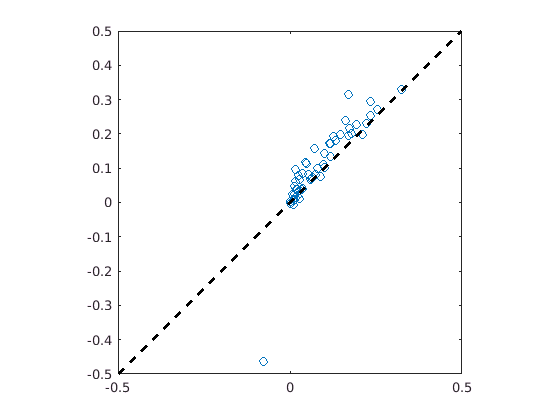

figure
plot(kinModelDLR2,muscleModelDLR2,'o')
hold on
plot([-1 1],[-1 1], 'k--','linewidth',2)
axis equal
xlim([-0.5 0.5])
ylim([-0.5 0.5])

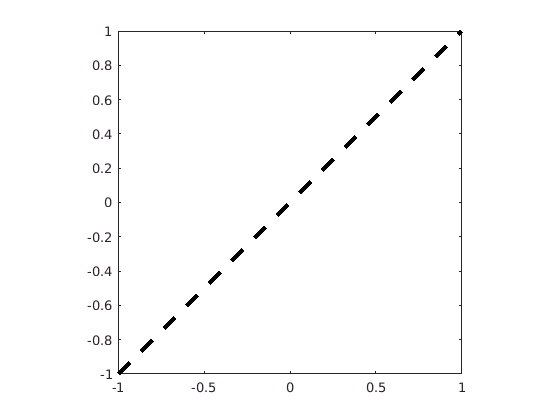


figure
plot(kinModelAcrossDLR2,muscleModelAcrossDLR2,'o')
hold on
plot([-1 1],[-1 1], 'k--','linewidth',3)
axis equal
xlim([-1 1])
ylim([-1 1])

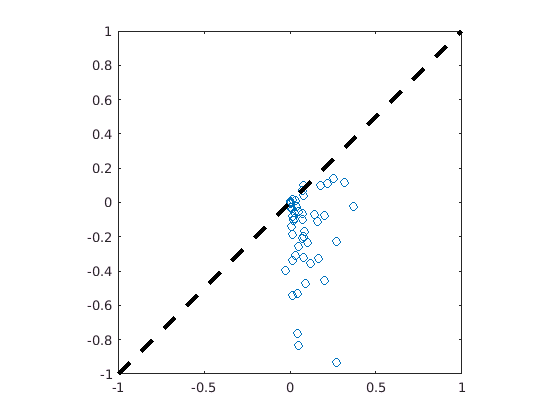


figure
plot(kinModelPMR2,kinModelAcrossDLR2,'o')
hold on
plot([-1 1],[-1 1], 'k--','linewidth',3)
axis equal
xlim([-1 1])
ylim([-1 1])

## Try PCA on muscles to examine covariance patterns

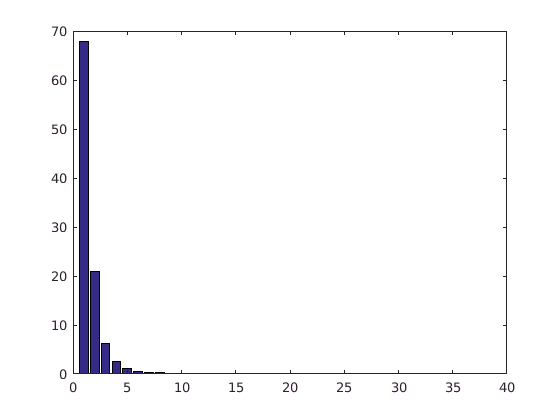

[coeffPM,~,~,~,explainedPM] = pca(muscleVelPM.Variables);
[coeffDL,~,~,~,explainedDL] = pca(muscleVelDL.Variables);

figure
bar(explainedPM)

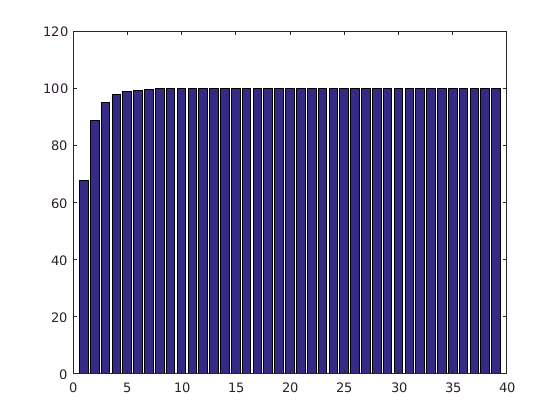


figure
bar(cumsum(explainedPM))